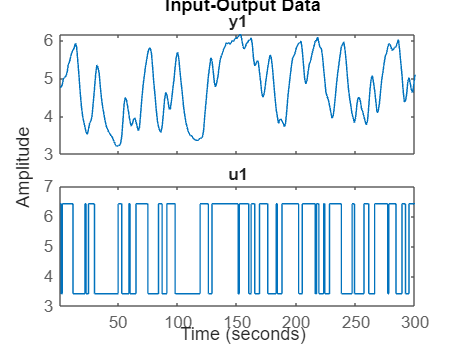

% load data
load dryer2

% Combine y2 and u2 for the first 300 data points
z2_iddata = iddata(y2(1:300), u2(1:300));

% Plot iddata (idplot does not require additional parameters like 1:300 or 0. 08)
figure(1)
idplot(z2_iddata); % Plot the input-output data directly

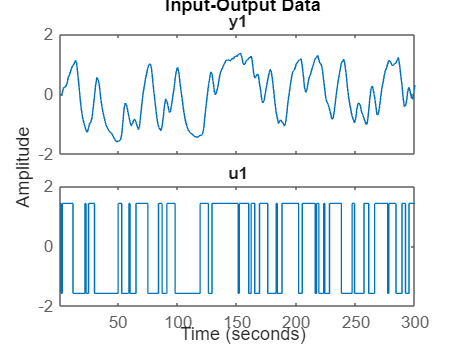


% -------------------------------------------------------
% Step 3: Detrend data
z3_detrended = dtrend(z2_iddata);

% Plot detrended data
figure(2)
idplot(z3_detrended);               % Again, no need for extra

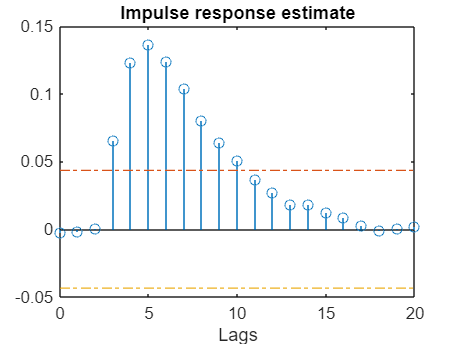


% Step 4: Compute impulse response using CRA (Correlation Analysis)
figure(3)
ir = cra(z3_detrended);             % Use detrended data for CRA (fixed variable name)


% Step 5: Estimate ARX model paramecers
th = arx(z3_detrended, [2 2 3]);    % Use detrended data for ARX model (fixed variable name)
th = sett(th, 0.08);                % Set sampling interval (0.08 sec)
present(th);                        % Display the ARX model parameters

th =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.274 z^-1 + 0.3942 z^-2              
                                                   
  B(z) = 0.06679 z^-3 + 0.04429 z^-4               
                                                   
Sample time: 0.08 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=3
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                         
Model modified after estimation.
More information in model's "Report" property.
 
Model Properties


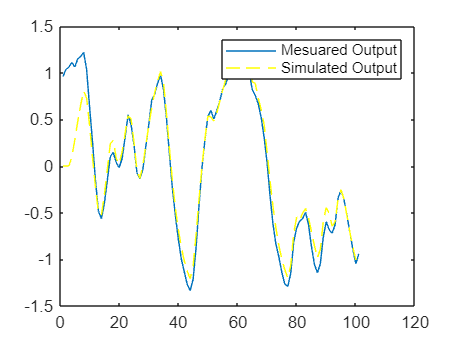


% Step 6: Validate the ARX model
u = dtrend(u2(800 : 900));          % Detrend the input data for validation
y = dtrend(y2(800 : 900));          % Detrend the output data for validation
yh = idsim(u, th);                  % Simulate the model output

% Plot the measured and simulated output
figure(4)
plot(y);
hold on;
plot(yh, 'y--');                    % Plot the simulated output in yellow dashed line
legend('Mesuared Output', 'Simulated Output');